project_root = "~/tagslam_ws/tagslam_root/src/continuum_mocap";
bags_dir = fullfile(project_root, "bags");

all_bag_files = dir(fullfile(bags_dir, '**/*.*'));  %get list of files and folders in any subfolder
all_bag_files = all_bag_files(~[all_bag_files.isdir]);  %remove folders from list

selection_mask = zeros(size(all_bag_files));
for i = 1 : length(all_bag_files)
    if contains(all_bag_files(i).name, "localized")
        selection_mask(i) = 1;
    end
end

tagslam_bags = all_bag_files(logical(selection_mask));

bag = rosbag(fullfile(tagslam_bags(1).folder, tagslam_bags(1).name)); % Test with 10psi bag
% TODO: Get the tag poses!!

planar_snake_tags = 6:9; % Tags 6 to 9

g_tags = cell(size(planar_snake_tags));
for i = 1 : length(planar_snake_tags)
    id_tag = planar_snake_tags(i);
    
    % Make sure that the tag we're looking for has an existing
    % transformation in the TF tree
    if ~any(bag.AvailableFrames == sprintf("tag_%d", id_tag))
        error("Tag with id %d not found in list of available frames", id_tag)
    end
    
    tform_i = getTransform(bag, "snake", "tag_" + id_tag);
    R = quat2rotm(tform_i.Transform.Rotation.readQuaternion());
    T_obj = tform_i.Transform.Translation;
    T = [T_obj.X; T_obj.Y; T_obj.Z];
    g_tags{i} = SE3(R, T);
end

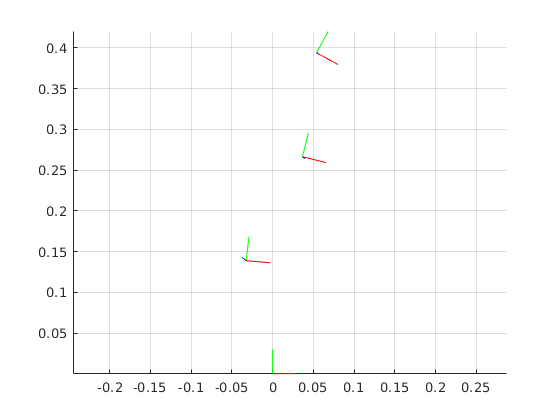

fig = figure();
ax = axes(fig);
grid on
axis equal

plot_options = struct();
plot_options.framesize = 0.03;
[gh_tforms, T_tforms, quat_tforms] = plotTransformsSE_n(g_tags, ax, plot_options);
view(0, 90)